clear
addpath(genpath(pwd));

opts = spreadsheetImportOptions("NumVariables", 11);

% Specify sheet and range
opts.Sheet = "InflowData";
opts.DataRange = "A2:K13680";

% Specify column names and types
opts.VariableNames = ["DatetimeCETCESTDDMMYYYYHHmm", "DMAALs", "DMABLs", "DMACLs", "DMADLs", "DMAELs", "DMAFLs", "DMAGLs", "DMAHLs", "DMAILs", "DMAJLs"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
InflowData1 = readtable("InflowData_1.xlsx", opts, "UseExcel", false)

InflowData1 = 13679×11 table
    DatetimeCETCESTDDMMYYYYHHmm    DMAALs    DMABLs    DMACLs    DMADLs    DMAELs    DMAFLs    DMAGLs    DMAHLs    DMAILs    DMAJLs
    ___________________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

       01-Jan-2021 00:00:00         NaN       NaN         3.7     NaN       NaN       NaN       NaN       NaN       NaN       NaN  
       01-Jan-2021 01:00:00         NaN       NaN      3.5625     NaN       NaN       NaN       NaN       NaN       NaN       NaN  
       01-Jan-2021 02:00:00         NaN       NaN      3.2725     Na


opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "WeatherData";
opts.DataRange = "A2:E13848";

% Specify column names and types
opts.VariableNames = ["DatetimeCETCESTDDMMYYYYHHmm", "RainfallDepthmm", "AirTemperatureC", "AirHumidity", "Windspeedkmh"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double"];

% Import the data
WeatherData1 = readtable("WeatherData_1.xlsx", opts, "UseExcel", false)

WeatherData1 = 13847×5 table
    DatetimeCETCESTDDMMYYYYHHmm    RainfallDepthmm    AirTemperatureC    AirHumidity    Windspeedkmh
    ___________________________    _______________    _______________    ___________    ____________

       01-Jan-2021 00:00:00                0                7.2              79               9     
       01-Jan-2021 01:00:00                0                7.3              79               6     
       01-Jan-2021 02:00:00                0                7.6              78               4     
       01-Jan-2021 03:00:00                0                8.2              75               4     
       01-Jan-2021 04:00:00                0                7.7              77               7     
       01-Jan-2021 05:00:00              0.1                7.5              81              

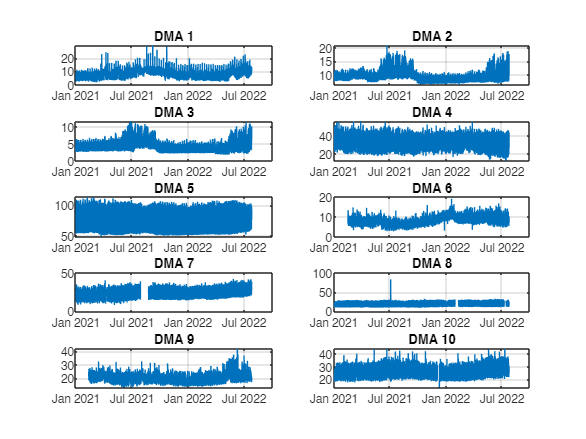




TQ = InflowData1.DatetimeCETCESTDDMMYYYYHHmm;
Q = table2array(InflowData1(:,2:11));
LogQ = log(Q);
Tweather = WeatherData1.DatetimeCETCESTDDMMYYYYHHmm;
W = table2array(WeatherData1(:,2:5));
Tw = Tweather(1:length(Q));
Rain = W(:,1);
AirT = W(:,2);
AirH = W(:,3);
Wind = W(:,4);


P = [162, 531, 607, 2094 , 7955, 1135, 3180, 2901, 425, 776]; % Population

dt = datetime(TQ, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');
figure;
for i = 1:10
    subplot(5,2,i);
    plot(TQ, Q(:,i));  
    title(['DMA ' num2str(i)]);
    grid on
end

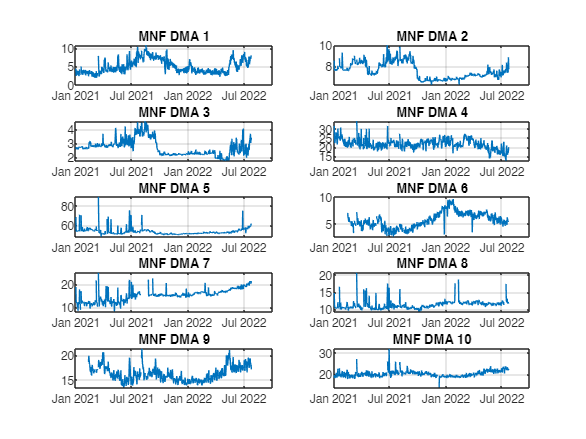

% Initialize the MNF matrix to store minimum values for each DMA
MNF = zeros(numel(unique(dateshift(dt, 'start', 'day'))), 10);

% Loop through each DMA
for i = 1:10
    % Extract the time series for the current DMA
    currentQ = Q(:,i);
    
    % Find unique days
    uniqueDays = unique(dateshift(dt, 'start', 'day'));
    
    % Loop through each day
    for j = 1:length(uniqueDays)
        % Find the indices for the current day
        dayIndices = dt >= uniqueDays(j) & dt < uniqueDays(j) + days(1);
        
        % Find the minimum value for the current day and current DMA
        MNF(j,i) = nanmin(currentQ(dayIndices));
    end
end

% Plotting the results
figure;  % Ensure a new figure is created for the plots
for i = 1:10
    subplot(5,2,i);
    plot(uniqueDays, MNF(:,i));  
    title(['MNF DMA ' num2str(i)]);
    grid on
end

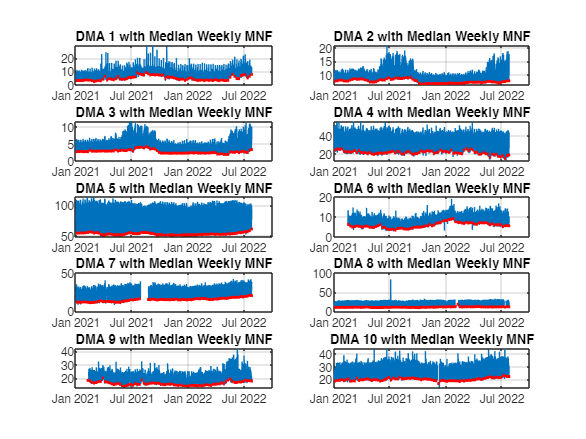


% Calculate Median MNF Per Week:
% Determine the number of weeks
numWeeks = ceil(days(uniqueDays(end) - uniqueDays(1))/7);

% Initialize the matrix for median MNF per week
medianMNFPerWeek = zeros(numWeeks, 10);

% Calculate median MNF per week for each DMA
for i = 1:10
    for week = 1:numWeeks
        % Define the week's range
        weekStart = uniqueDays(1) + days(7*(week-1));
        weekEnd = weekStart + days(7);
        
        % Find the indices for the current week
        weekIndices = uniqueDays >= weekStart & uniqueDays < weekEnd;
        
        % Calculate the median value for the current week and current DMA
        medianMNFPerWeek(week,i) = nanmedian(MNF(weekIndices,i));
    end
end

    % Plotting the original Q values and the median weekly MNF
figure;  % Create a new figure for the plots
for i = 1:10
    subplot(5,2,i);
    
    % Plot original Q values
    plot(dt, Q(:,i));
    hold on;  % Hold on to add more to the current plot
    
    % Plot median MNF per week as horizontal lines
    for week = 1:numWeeks
        weekStart = uniqueDays(1) + days(7*(week-1));
        weekEnd = weekStart + days(7);
        line([weekStart, weekEnd], [medianMNFPerWeek(week, i), medianMNFPerWeek(week, i)], 'Color', 'r', 'LineWidth', 2);
    end
    
    % Add title and grid
    title(['DMA ' num2str(i) ' with Median Weekly MNF']);
    grid on;
    hold off;  % Release the plot
end


% Initialize the matrix for estimated leakage per hour
estimatedLeakage = zeros(size(Q));

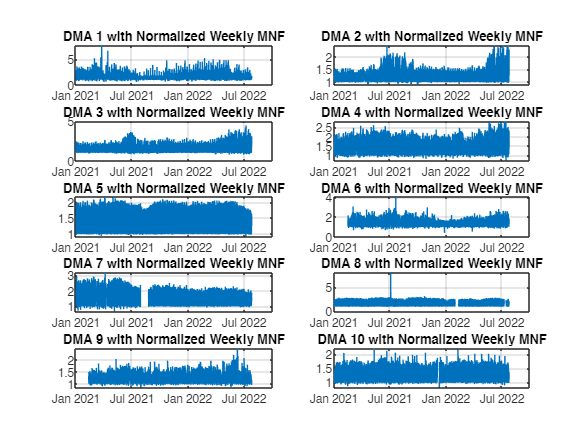

% Calculate estimated leakage for each hour for each DMA
for i = 1:10
    % Get the weekly median MNF for the current DMA
    currentMedianMNF(:,i) = interp1(1:numWeeks, medianMNFPerWeek(:,i), ceil((1:length(dt))/168), 'previous', 'extrap');
end
Qnorm = Q./currentMedianMNF;
figure
for i = 1:10
    subplot(5,2,i);
    % Plot original Q values
    plot(dt, Qnorm(:,i));
    % Add title and grid
    title(['DMA ' num2str(i) ' with Normalized Weekly MNF']);
    grid on;
    hold off;  % Release the plot
end

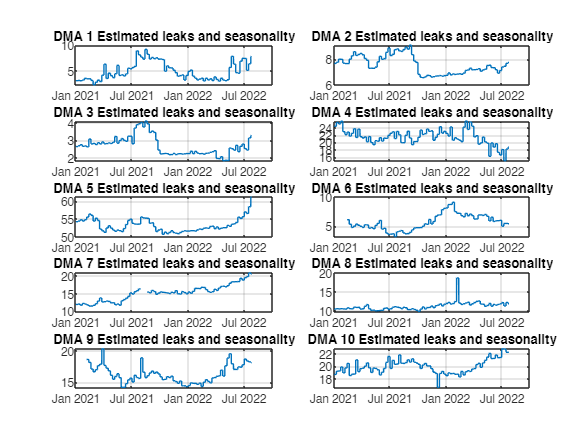


figure
for i = 1:10
    subplot(5,2,i);
    % Plot original Q values
    plot(dt, currentMedianMNF(:,i));
    % Add title and grid
    title(['DMA ' num2str(i) ' Estimated leaks and seasonality']);
    grid on;
    hold off;  % Release the plot
end

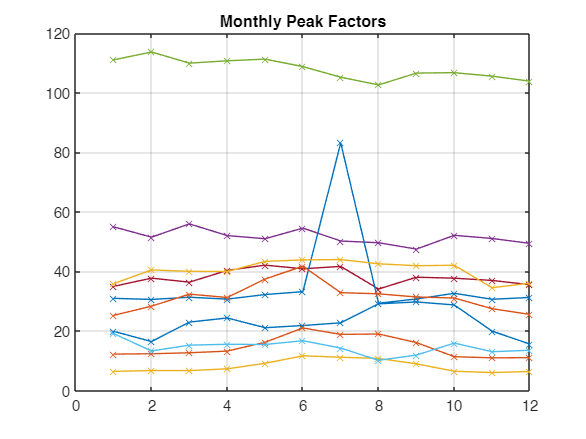

% Convert the datetime to proper format if it's not already
dt = datetime(TQ, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');

% Preallocate the peak factor arrays
pfMonthly = zeros(12, size(Qnorm, 2));  % 12 months
pfDaily = zeros(7, size(Qnorm, 2));     % 7 days of the week
pfHourly = zeros(24, size(Qnorm, 2));   % 24 hours

% Calculate Monthly Peak Factors
for months = 1:12
    for dma = 1:size(Qnorm, 2)
        monthlyData = Qnorm(month(dt) == months, dma);
        pfMonthly(months, dma) = nanmedian(monthlyData);  % Compute mean excluding NaNs
    end
end
%pfMonthly = pfMonthlyA./mean(pfMonthlyA);

% Calculate Daily Peak Factors
Q2 = Qnorm./pfMonthly(month(dt),:);
for days = 1:7
    for dma = 1:size(Q2, 2)
        dailyData = Q2(day(dt, 'dayofweek') == days, dma);
        pfDaily(days, dma) = nanmedian(dailyData);  % Compute mean excluding NaNs
    end
end

% Calculate Hourly Peak Factors
Q3 = Q2./pfDaily(day(dt, 'dayofweek'),:);
for hours = 1:24
    for dma = 1:size(Q3, 2)
        hourlyData = Q3(hour(dt) == hours-1, dma);  % -1 because MATLAB hours are 0-23
        pfHourly(hours, dma) = nanmedian(hourlyData);  % Compute mean excluding NaNs
    end
end

% Output the peak factors
figure
plot(pfMonthly,'-x')
grid on
title('Monthly Peak Factors')

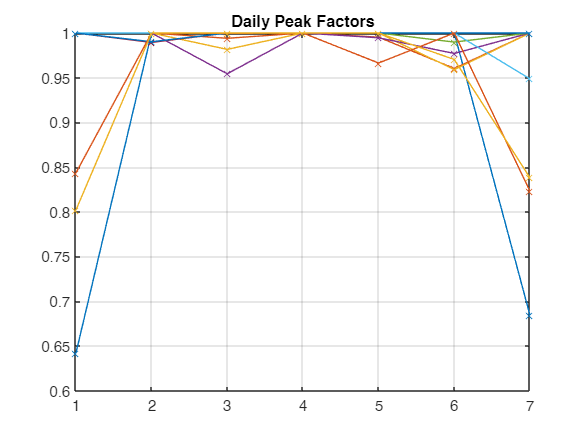

figure
plot(pfDaily,'-x')
grid on
title('Daily Peak Factors')

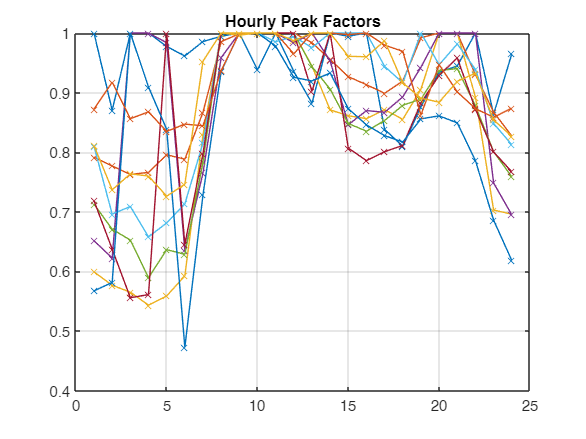

figure
plot(pfHourly,'-x')
grid on
title('Hourly Peak Factors')

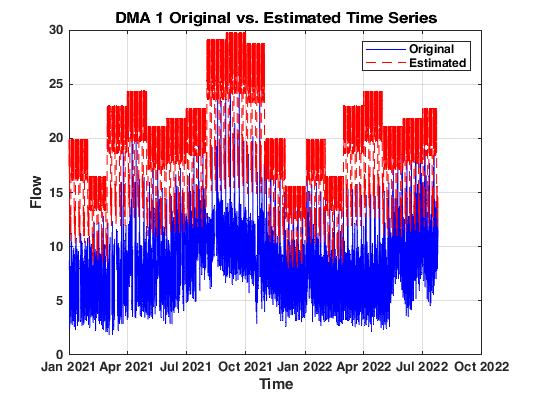

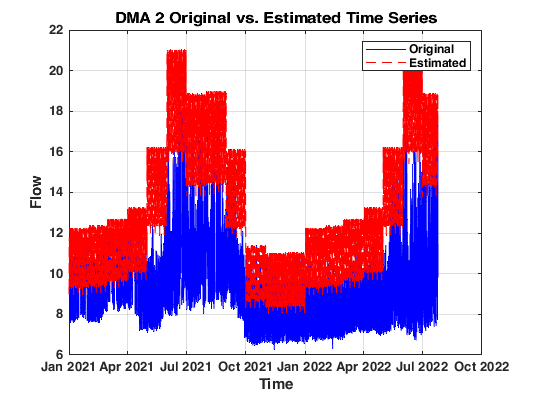

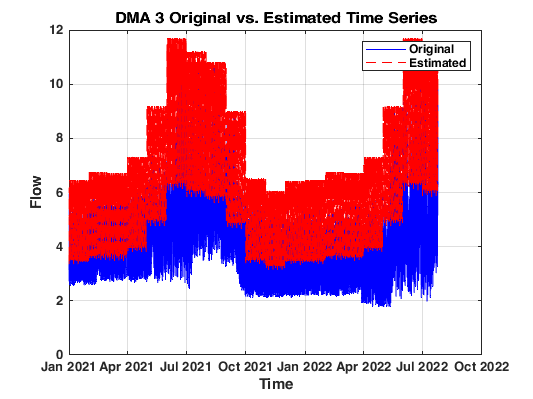

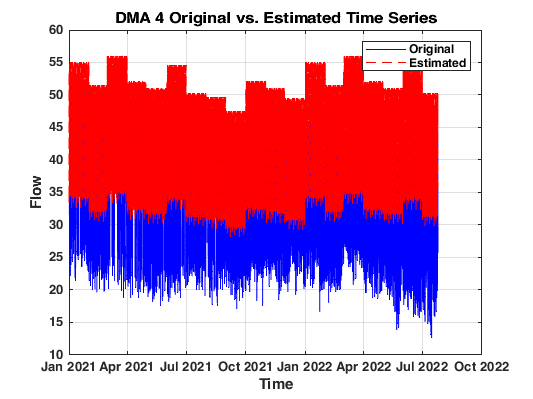

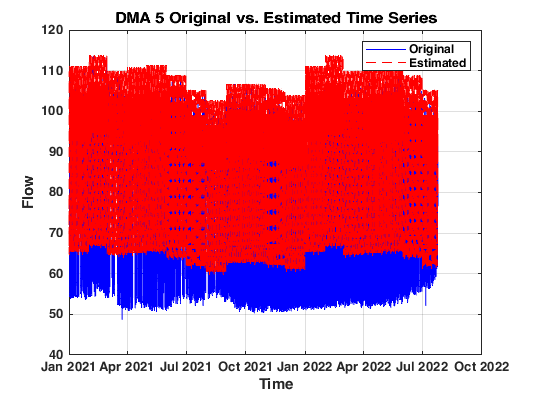

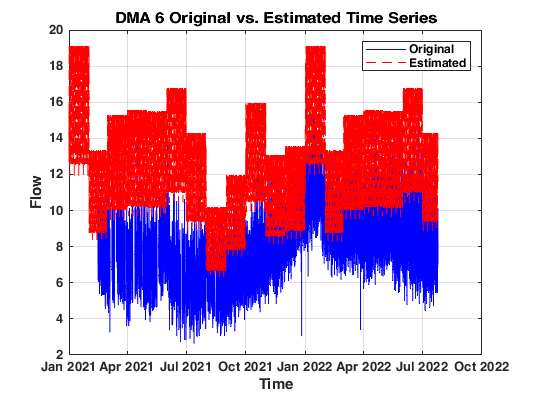

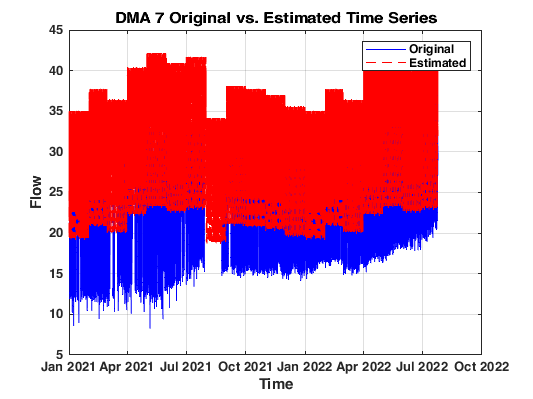

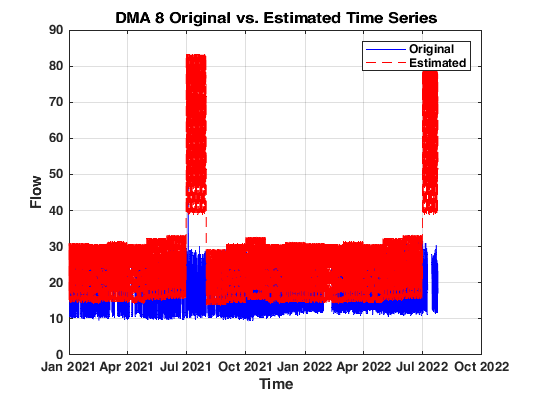

% Ensure you have the pfMonthly, pfDaily, and pfHourly from the previous step
% And Q is your original data, datetime is your array of datetime objects

% Preallocate the estimated matrix
Q_estimated = zeros(size(Qnorm));

% Construct the estimated time series
for dma = 1:size(Qnorm, 2)
    for t = 1:length(dt)
        months = month(dt(t));
        days = day(dt(t), 'dayofweek');
        hours = hour(dt(t));
        
        % Compute the estimated value
        Q_estimated(t, dma) = pfMonthly(months, dma) * pfDaily(days, dma) * pfHourly(hours+1, dma);
        %Q_estimated(t, dma) = pfHourly(hours+1, dma);
    end
end

% Plotting the original and estimated time series for each DMA
for dma = 1:size(Qnorm, 2)
    figure; % Create a new figure for each DMA
    
    % Plotting the original data
    plot(dt, Qnorm(:, dma), 'b', 'DisplayName', 'Original');
    hold on; % Hold on to plot the estimated data on the same figure
    
    % Plotting the estimated data
    plot(dt, Q_estimated(:, dma), 'r--', 'DisplayName', 'Estimated');
    
    %err(:,dma) = Q(:, dma)-Q_estimated(:, dma);

    %plot(dt, err(:,dma) ,'k-', 'DisplayName', 'error');
    % Adding title and labels
    title(['DMA ' num2str(dma) ' Original vs. Estimated Time Series']);
    xlabel('Time');
    ylabel('Flow');
    legend show;
    
    % Add grid for better readability
    grid on;
end